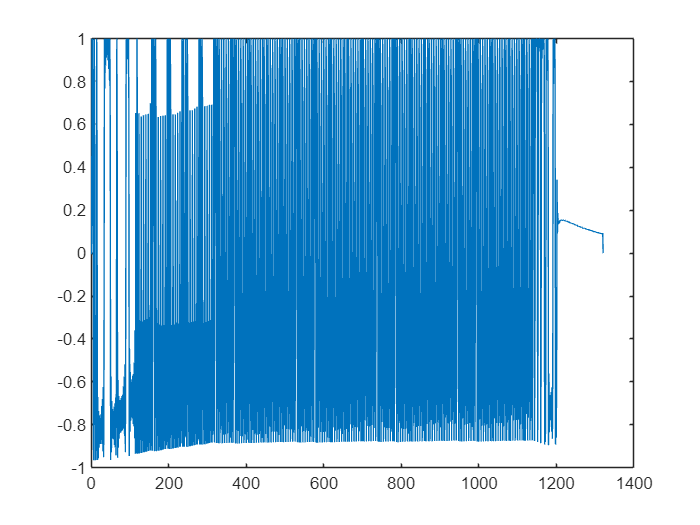

i= 32;
plot(audio_rec(i, :))

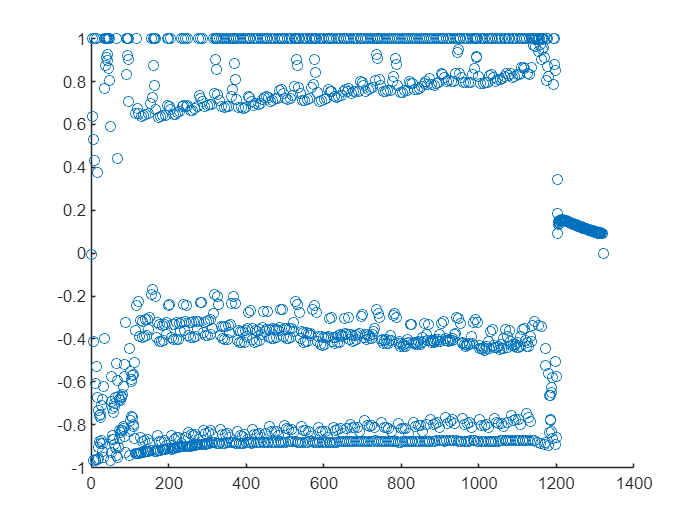

scatter(1:length(audio_rec(i, :)),audio_rec(i, :))

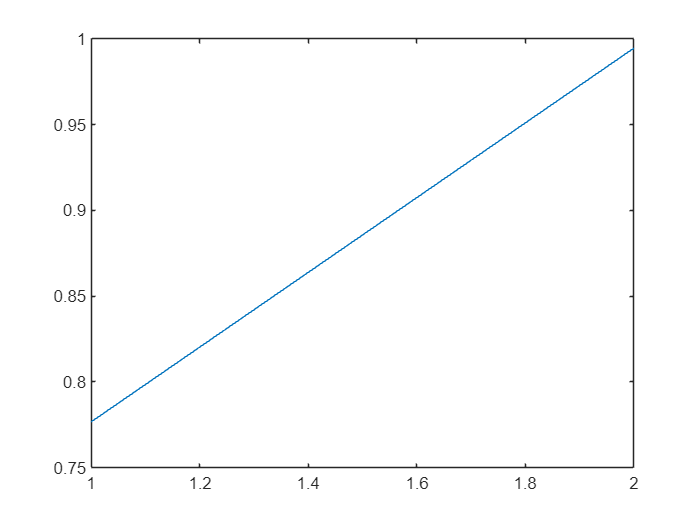


%sym = audio(1, 481:489);
sym2 = audio_rec(1, 1:2);
plot(sym2)

index = 2;
% a = audio(index, 480:end);
% b = audio_rec(index, 1:length(a));
% plot(abs(a - b))
%org = demodd(audio(index, 480:end), sym);
%plot(org)
recd = demodd(audio_rec(index, :), sym2);

错误使用 dot
A 和 B 的大小必须相同。

出错 p2>demodd (第 29 行)
        res(k) = dot(arr((i-2):i), sym);

plot(recd)
plot(abs(org - recd))

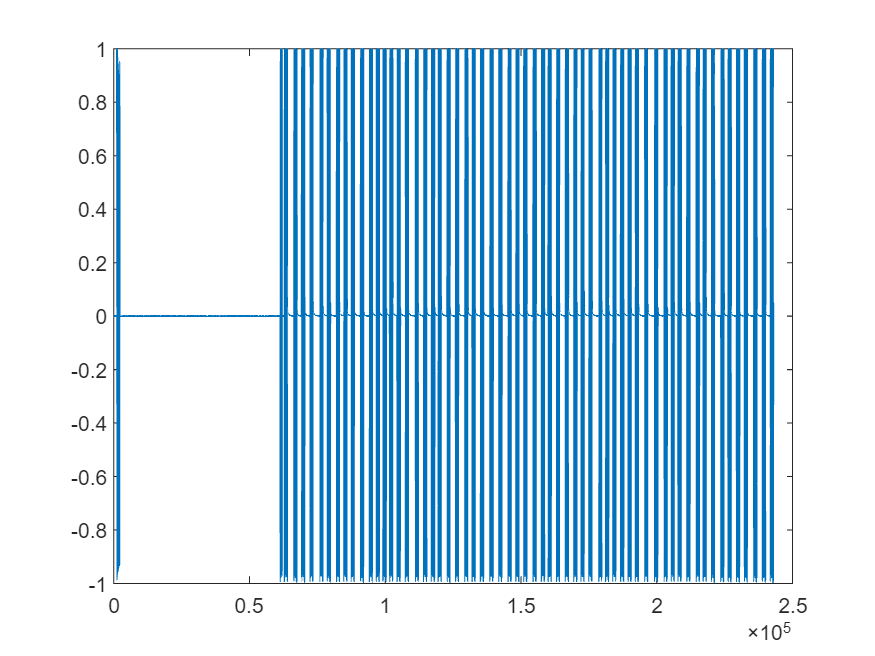

a = audioread("debug0.wav")';
%b = audioread("debug1.wav")';
plot(a)

plot(b)

函数或变量 'b' 无法识别。

plot(audio)

%audiowrite("debugwaw.wav", audio, 48000);

function res = demodd(arr, sym)
    res = zeros(1, 1400);
    k = 0;
    for i = 3:2:length(arr)
        k = k + 1;
        res(k) = dot(arr((i-2):i), sym);

    end
end